%  result4- with abs min ending point Duration

clc;
clear all;
clearvars;

%Polmak
% for i=1:size(intervals,2)
IIP_Duration_Pol=xlsread("Result4\Polmak\IIP_Duration.xlsx",'10');
rows_Pol=size(IIP_Duration_Pol,1)-1;
Average_duration_Pol=mean(IIP_Duration_Pol(1:rows_Pol,1));
for i2_Pol=1:rows_Pol
    IIP_Duration_Pol(i2_Pol,2)=IIP_Duration_Pol(i2_Pol,1)-Average_duration_Pol;
end
bar(IIP_Duration_Pol(:,end),'EdgeColor','none','FaceColor',[0 0 0]);
xlabel('Year')
ylabel('Duration anomalies')
title('Tana, anomalies from average freezing duration')
set(gca,'FontSize',12,'FontName','Times New Roman','XTickLabel',...
    {'1910','1930','1950','1970','1990','2010'})
V_Pol=IIP_Duration_Pol(50:end,2);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

H_Pol = logical
   1


p_value_Pol = 0.0245

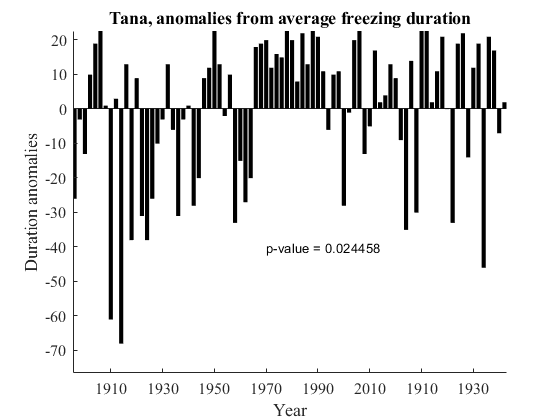

text1=['p-value = ' num2str(p_value_Pol)];
text(50,-40,text1)
box('off')

clc;
clear all;
clearvars;

%Kukko
IIP_Duration_Kuk=xlsread("Result4\Kukko\IIP_Duration.xlsx",'10');
rows_Kuk=size(IIP_Duration_Kuk,1)-2;
Average_duration_Kuk=mean(IIP_Duration_Kuk(1:rows_Kuk,1));
for i2_Kuk=1:rows_Kuk
    IIP_Duration_Kuk(i2_Kuk,2)=IIP_Duration_Kuk(i2_Kuk,1)-Average_duration_Kuk;
end
bar(IIP_Duration_Kuk(:,end),'EdgeColor','none','FaceColor',[0 0 0]);
xlabel('Year')
ylabel('Duration anomalies')
title('Tornio, anomalies from average freezing duration')
set(gca,'FontSize',12,'FontName','Times New Roman','XTickLabel',...
    {'1910','1930','1950','1970','1990','2010'})
V_Kuk=IIP_Duration_Kuk(:,2);
alpha_Kuk=0.05;
[H_Kuk,p_value_Kuk]=Mann_Kendall(V_Kuk,alpha_Kuk)

H_Kuk = logical
   0


p_value_Kuk = 0.2908

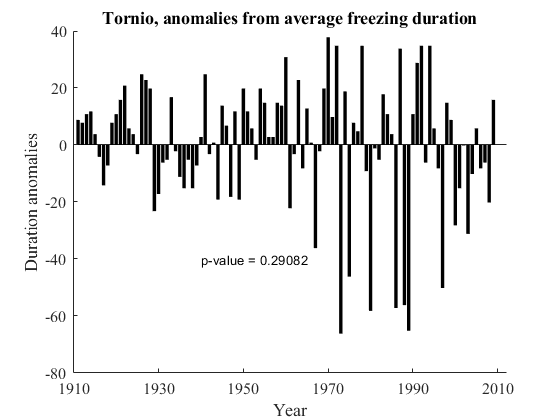

text1=['p-value = ' num2str(p_value_Kuk)];
text(30,-40,text1)
box('off')

% %2nd result-Shifts

% clc;
% clear all;
% clearvars;

% %Polmak
% day_Pol=xlsread("Result4\Polmak\day.xlsx",'10');
% dates_Pol=xlsread("Polmak\startstopdate.xlsx",'10');
% Years_Pol=str2num(datestr(x2mdate(dates_Pol(:,2)),'yyyy'));
% % Start
% plot(Years_Pol(:,1),day_Pol(:,1),'.');
% V_Pol=day_Pol(:,1);
% alpha_Pol=0.05;
% [H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)
% % End
% plot(Years_Pol(:,1),day_Pol(:,2),'.');
% V_Pol=day_Pol(:,2);
% alpha_Pol=0.05;
% [H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

% clc;
% clear all;
% clearvars;

% %Kukko
% day_Kuk=xlsread("Result4\Kukko\day.xlsx",'10');
% dates_Kuk=xlsread("Kukko\startstopdate.xlsx",'10');
% Years_Kuk=str2num(datestr(x2mdate(dates_Kuk(:,2)),'yyyy'));
% % Start
% plot(Years_Kuk(:,1),day_Kuk(:,1),'.');
% V_Kuk=day_Kuk(:,1);
% alpha_Kuk=0.05;
% [H_Kuk,p_value_Kuk]=Mann_Kendall(V_Kuk,alpha_Kuk)
% % End
% plot(Years_Kuk(:,1),day_Kuk(:,2),'.');
% V_Kuk=day_Kuk(:,2);
% alpha_Kuk=0.05;
% [H_Kuk,p_value_Kuk]=Mann_Kendall(V_Kuk,alpha_Kuk)

